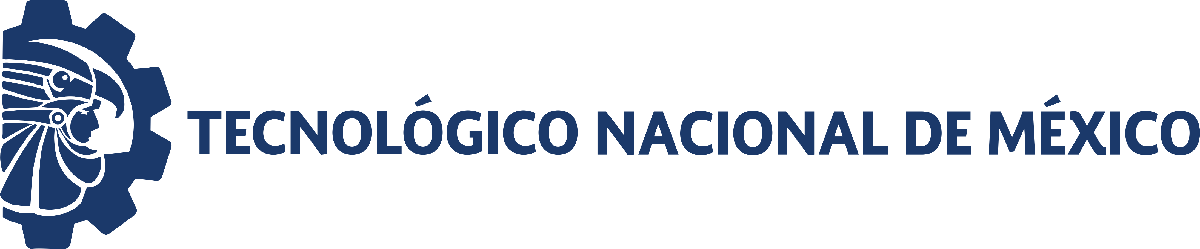                                 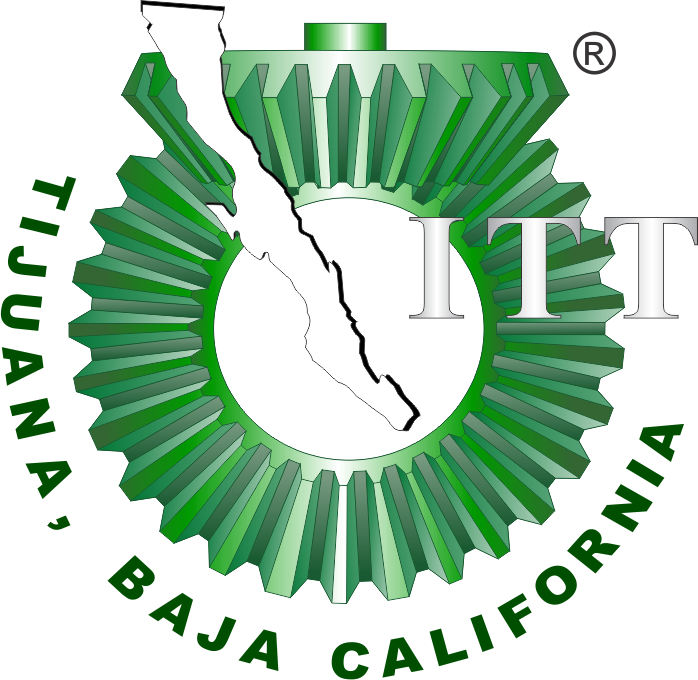

# Práctica dos: Sistema Respiratorio 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

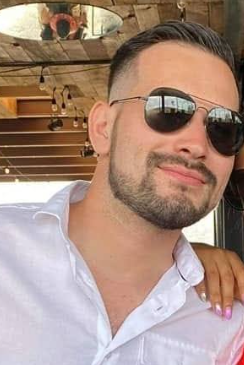

Nombre del alumno: Diego David Villaseñor Lopez

Número de control: 22210431

Correo institucional: l22210431**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='Villasenor22210431';
open_system(file);
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
parameters.StopTime='30';

## Rendimiento del controlador

Kp= 16.979

Kp = 16.9790

Ki=71.3033

Ki = 71.3033

KD=0.38657

KD = 0.3866

settlingtime=25.2481

settlingtime = 25.2481

Overshoot=8.89%

Overshoot = 8.8900

Peak=1.09

Peak = 1.0900

## Respiracion normal

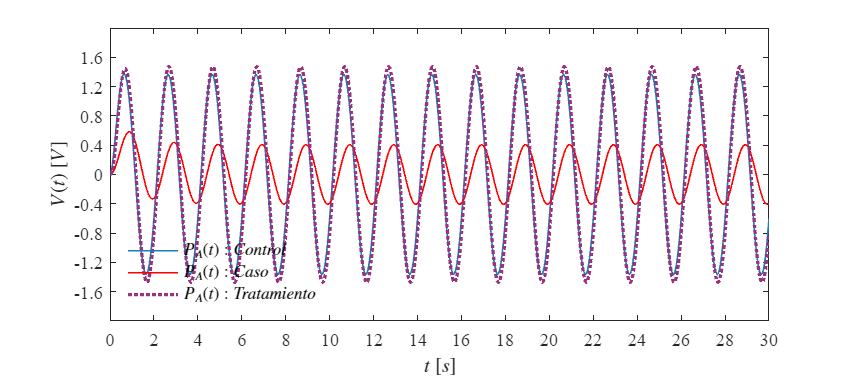

Signal='Respiracion normal';
set_param('Villasenor22210431/Pao(t)','sw','0');
set_param('Villasenor22210431/PID Controller','P','16.979');
set_param('Villasenor22210431/PID Controller','I','71.3033');
set_param('Villasenor22210431/PID Controller','D','0.38657');
N=sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiracion anormal

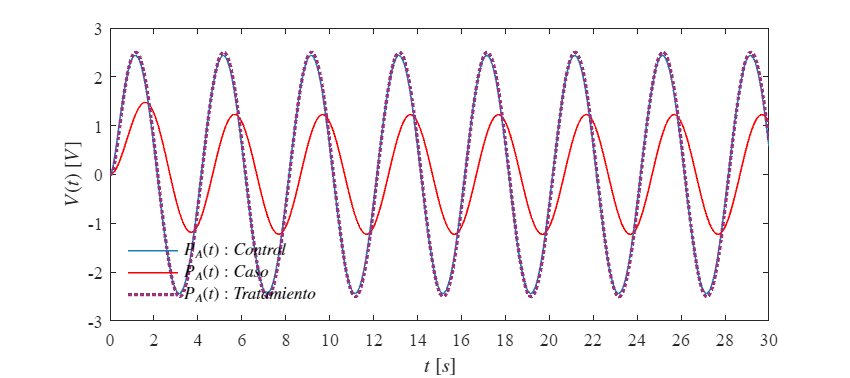

Signal='Respiracion anormal';
set_param('Villasenor22210431/Pao(t)','sw','1');
set_param('Villasenor22210431/PID Controller','P','16.979');
set_param('Villasenor22210431/PID Controller','I','71.3033');
set_param('Villasenor22210431/PID Controller','D','0.38657');
N1=sim(file,parameters);
plotsignals(N1.t,N1.PAx,N1.PAy,N1.PAz,Signal)

## Funcion: Respuesta a las señales 

function plotsignals(t,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(11,'points')
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
    hold on;grid off; box on;

    plot(t,PAx,'LineWidth',1,'Color',azul)
    plot(t,PAy,'LineWidth',1,'Color',rojo)
    plot(t,PAz,':','LineWidth',2,'Color',morado)

    xlabel('$t$ $[s]$','Interpreter','latex')
    ylabel('$V(t)$ $[V]$','Interpreter','latex')
    
    L=legend('$P_{A}(t):Control$','$P_A(t):Caso$','$P_{A}(t):Tratamiento$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    
    if Signal=="Respiracion normal"
    xlim([0.0 30.0]); xticks(0:2:30)
    ylim([-2 2]); yticks(-1.6:0.4:1.6)
    elseif Signal=="Respiracion anormal"
    xlim([0.0 30.0]); xticks(0:2:30)
    ylim([-3 3]);yticks(-3:1:3)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end